**Accumarray() Function on Christmas Sales of Flat-Screen Televisions **

The holiday season presents a critical opportunity to analyze sales patterns and make informed decisions to optimize inventory and maximize revenue. For this analysis, I focused on flat-screen television sales during Christmas, leveraging MATLAB’s `accumarray` function to efficiently group and process data. This tool allowed me to aggregate sales by store and identify peak performance days, providing a deeper understanding of sales dynamics.

To simulate the sales data, I created vectors representing store IDs and their corresponding sales numbers. This structure captured raw data collected during the holiday season, allowing me to replicate the sales environment realistically. By using `accumarray`, I grouped the sales data by store ID and calculated total sales for each store. This step helped me determine which stores performed best overall, offering insights into location-based sales trends.

Next, I applied the `@max` function within `accumarray` to find the highest single-day sales for each store. This approach revealed peak demand periods, highlighting stores that experienced significant spikes in sales. Identifying these patterns is crucial for understanding customer behavior and preparing for future high-demand events.

To present the results, I visualized the data with a bar chart. I overlaid two datasets: total sales and maximum single-day sales for each store. This comparison allowed me to differentiate between stores with steady performance and those reliant on specific high-demand days. The visualization provided a clear and comprehensive view of sales dynamics across different locations.

By using `accumarray`, I efficiently processed grouped data without manual iteration. This streamlined approach enabled me to analyze large datasets quickly and accurately. Comparing total sales with maximum single-day sales helped me identify stores with consistent performance versus those with sporadic spikes. These insights are actionable, supporting strategic decisions such as restocking high-demand locations or targeting promotions to underperforming stores.

% Step 1: Simulate sales data
stores = [1; 1; 2; 2; 3; 3; 1; 2; 3; 3; 2; 1]; 
% I created a vector representing the store IDs. Each number corresponds to a different store.

sales = [5; 8; 10; 12; 15; 7; 6; 9; 20; 18; 11; 4]; 
% I simulated the number of televisions sold at each store on specific days.

% Step 2: Total sales by store
totalSalesByStore = accumarray(stores, sales, [], @sum); 
% I used `accumarray` to group sales data by store and sum the sales for each store. This helped me see total sales per store.

disp('Total Sales by Store:'); 

Total Sales by Store:


disp(totalSalesByStore); 

    23
    42
    60



% I displayed the total sales for each store to verify the calculations.

% Step 3: Find the maximum single-day sales by store
maxSalesByStore = accumarray(stores, sales, [], @max); 
% I used `accumarray` again, but this time with the `@max` function, to find the highest single-day sales for each store.

disp('Maximum Single-Day Sales by Store:'); 

Maximum Single-Day Sales by Store:


disp(maxSalesByStore); 

     8
    12
    20



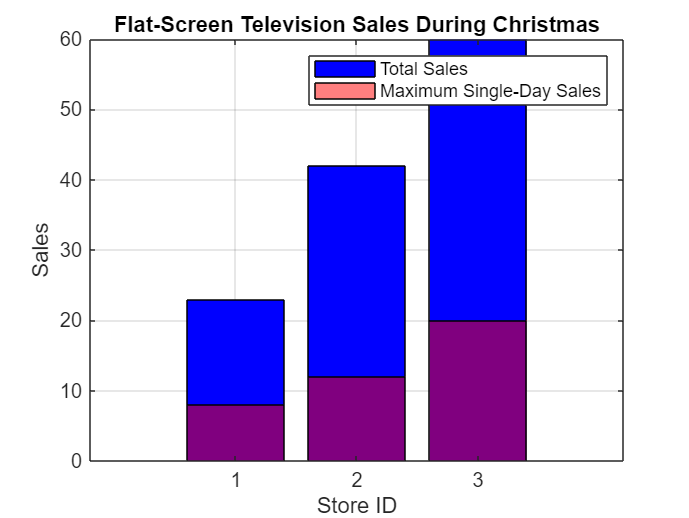

% I displayed the maximum sales for each store to identify peak performance days.

% Step 4: Visualize the results
storeIDs = unique(stores); 
% I extracted unique store IDs to use as x-axis labels in the bar plot.

figure; 
% I opened a new figure to plot the results.

bar(storeIDs, totalSalesByStore, 'FaceColor', 'b'); 
% I created a bar chart to visualize total sales by store. I chose blue to represent holiday sales.

hold on; 
% I used `hold on` to overlay another bar chart on the same figure.

bar(storeIDs, maxSalesByStore, 'FaceColor', 'r', 'FaceAlpha', 0.5); 
% I added a second bar chart for maximum single-day sales using red with some transparency.

xlabel('Store ID'); 
ylabel('Sales'); 
title('Flat-Screen Television Sales During Christmas'); 
legend('Total Sales', 'Maximum Single-Day Sales'); 
grid on; 

% I labeled the axes, added a title, and included a legend and grid for clarity.
